## Naïve Bayes Analysis Part 1

In this script Matlab's automated hyperparameter optimization search is used to:

- Find out if dataset normalisation performs better.

- Find which distribution name is better (normal or kernel?).

- Find the optimal range of kernel smoothing widths.

- Investigate the prior distributions created by default compared to calculating them from the training dataset.

- Compare the performance of the dataset with all features vs the dataset with features removed

### Initial Analysis from a Naïve Bayes perspective dataset NOT normalised


clear
clc
clf
close all
% loads the letter dataset 
load letterDatasetClass.mat

letterDataset = letterDatasetNotNormalised;
[X, Y] = letterDataset.extractXYFromTable(letterDataset.trainTable);
X = table2array(X);
Y = table2array(Y);
% get a default class

startTime = 52.5781

nBayes = NBayesClass.getDefaultInstance(letterDataset);
nBayes.nBayesModel.Prior

ans =     0.0391    0.0381    0.0381    0.0399    0.0384    0.0378    0.0393    0.0361    0.0379    0.0361    0.0367    0.0384    0.0396    0.0383    0.0382    0.0407    0.0386    0.0375    0.0381    0.0413    0.0404    0.0393    0.0377    0.0387    0.0394    0.0366


[dfltLTrainLoss, dfltTestLoss] = nBayes.getModelLoss();
nBayes.setPriorDistributionEmpirical();
nBayes.nBayesModel.Prior

ans =     0.0413    0.0379    0.0399    0.0383    0.0393    0.0391    0.0396    0.0387    0.0382    0.0375    0.0381    0.0361    0.0381    0.0361    0.0384    0.0381    0.0384    0.0394    0.0386    0.0407    0.0393    0.0377    0.0404    0.0378    0.0366    0.0368


**Compare the model between using the default prior distribution, or an empirical one calculated from the training dataset.**

[empTrainLoss, emptTestLoss] = nBayes.getModelLoss();
fprintf("Default Training Loss:   %0.04f Test Loss %0.04f\n", dfltLTrainLoss, dfltTestLoss);

Default Training Loss:   0.3539 Test Loss 0.3668


fprintf("Empirical Training Loss: %0.04f Test Loss %0.04f\n", empTrainLoss, emptTestLoss);

Empirical Training Loss: 0.3549 Test Loss 0.3678


**Setting the prior distribution to an empirical distribution:**

- **Does not affect the  model loss.**

- **Ensures that the initial prior distribution used is known.**

**The confusion matrix is displayed to see if there are any serious problems with any one of the predicted classes:**

model = nBayes.setPriorDistributionEmpirical();
cvModel = crossval(model);
modelLoss = kfoldLoss(cvModel);
crossValModel = crossval(model);
fprintf("KFold Loss:: %0.04f\n", kfoldLoss(crossValModel));

KFold Loss:: 0.3595


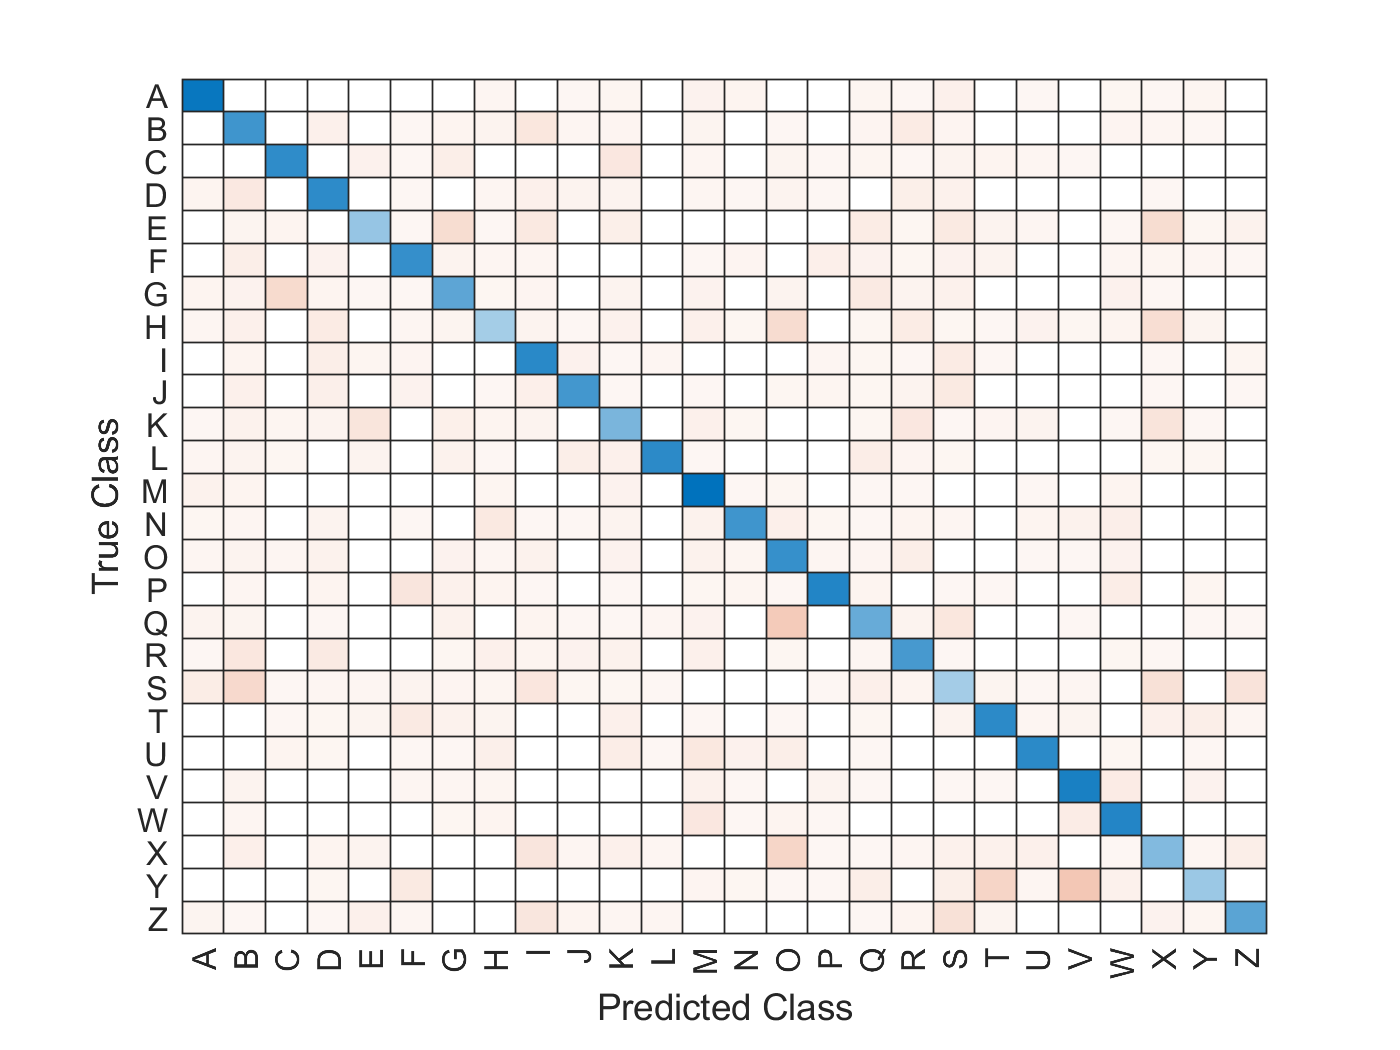

% start timer
startTime = cputime;
[predicted, score] = resubPredict(model);
endTime = cputime;
totalTime = endTime - startTime;
fprintf("Total cpu time (seconds): %02.04f", totalTime);
fig = figure;
confusionMat = confusionchart(categorical(Y), predicted,'RowSummary','row-normalized','ColumnSummary','column-normalized');

No problems stand out in the confusion chart.

fig_Position = fig.Position;

  Columns 1 through 7

    {'normal'}    {'normal'}    {'normal'}    {'normal'}    {'normal'}    {'normal'}    {'normal'}

  Columns 8 through 14

    {'normal'}    {'normal'}    {'normal'}    {'normal'}    {'normal'}    {'normal'}    {'normal'}

  Columns 15 through 16

    {'normal'}    {'normal'}



fig_Position(3) = fig_Position(3)*1.5;
fig.Position = fig_Position;

Look at the classifiers that have been setup for each attribute. There are 16 of them, each one configurable.

disp(model.DistributionNames(:,:));

Training loss: 0.3549 Test loss: 0.3678, normalised dataset: 0


Total cpu time (seconds): 13.7500

**The performance is noted for later analysis:**

[trainingLoss, testLoss] = nBayes.getModelLoss();

  NBayesClass with properties:

            randomSeed: 300
                 debug: 0
               dataset: [1×1 LetterDatasetClass]
           nBayesModel: [1×1 ClassificationNaiveBayes]
                     x: [16000×16 table]
                     y: [16000×1 table]
                    xt: [4000×16 table]
                    yt: [4000×1 table]
      distNamesDefault: {1×16 cell}
       distNamesKernel: {1×16 cell}
             smoothBox: {1×16 cell}
    smoothEpanechnikov: {1×16 cell}
           smootNormal: {1×16 cell}
        smoothTriangle: {1×16 cell}
         smoothUnsused: {1×16 cell}



fprintf("Training loss: %0.04f Test loss: %0.04f, normalised dataset: %d\n", trainingLoss, testLoss, nBayes.dataset.isStandardised);
disp(nBayes);

#### Try Optimization

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |
|=====================================================================================================|
|    1 | Best   |     0.33644 |      74.106 |     0.33644 |     0.33644 |       kernel |        1.287 |


|    2 | Accept |     0.35725 |       0.599 |     0.33644 |     0.34644 |       normal |            - |


|    3 | Accept |     0.35725 |     0.59414 |     0.33644 |     0.33644 |       normal |            - |


|    4 | Accept |     0.51019 |      71.126 |     0.33644 |     0.33644 |       kernel |       8.6162 |


|    5 | Best   |     0.25006 |      44.139 |     0.25006 |     0.25007 |       kernel |      0.30805 |


|    6 | Best   |     0.24919 |      44.191 |     0.24919 |     0.24914 |       kernel |      0.25009 |


|    7 | Accept |     0.24919 |      44.743 |     0.24919 |     0.24916 |       kernel |      0.25013 |


|    8 | Accept |     0.24919 |      44.628 |     0.24919 |     0.24917 |       kernel |      0.25022 |


|    9 | Accept |     0.24919 |      44.269 |     0.24919 |     0.24917 |       kernel |      0.26337 |


|   10 | Accept |     0.24919 |      44.202 |     0.24919 |     0.24917 |       kernel |      0.25043 |


|   11 | Accept |     0.27044 |      57.365 |     0.24919 |     0.24922 |       kernel |      0.61428 |


|   12 | Accept |     0.61375 |      70.957 |     0.24919 |      0.2492 |       kernel |       14.998 |


|   13 | Accept |     0.24938 |      44.282 |     0.24919 |     0.24924 |       kernel |      0.27578 |


|   14 | Accept |     0.44525 |      74.592 |     0.24919 |     0.24919 |       kernel |       3.1633 |


|   15 | Accept |     0.24931 |      44.205 |     0.24919 |      0.2492 |       kernel |      0.26992 |


|   16 | Accept |     0.25769 |      44.092 |     0.24919 |     0.24921 |       kernel |      0.44953 |


|   17 | Accept |     0.29875 |      65.613 |     0.24919 |     0.24921 |       kernel |      0.87686 |


|   18 | Accept |     0.48094 |      73.113 |     0.24919 |     0.24921 |       kernel |       5.1232 |


|   19 | Accept |      0.2525 |      44.219 |     0.24919 |     0.24921 |       kernel |      0.37089 |


|   20 | Accept |     0.39281 |      75.249 |     0.24919 |     0.24921 |       kernel |       1.9431 |


|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |
|=====================================================================================================|
|   21 | Accept |     0.25031 |      44.041 |     0.24919 |     0.24919 |       kernel |      0.33501 |


|   22 | Accept |     0.26306 |      57.424 |     0.24919 |     0.24919 |       kernel |      0.52137 |


|   23 | Best   |     0.24913 |      44.134 |     0.24913 |     0.24918 |       kernel |      0.25916 |


|   24 | Accept |     0.24944 |      44.079 |     0.24913 |     0.24918 |       kernel |      0.28773 |


|   25 | Accept |     0.24913 |      44.264 |     0.24913 |     0.24918 |       kernel |      0.25891 |


|   26 | Accept |     0.24913 |      44.061 |     0.24913 |     0.24917 |       kernel |       0.2586 |


|   27 | Accept |     0.54869 |      70.893 |     0.24913 |     0.24917 |       kernel |       11.674 |


|   28 | Accept |     0.28331 |      56.646 |     0.24913 |     0.24917 |       kernel |      0.72876 |


|   29 | Accept |       0.423 |      74.563 |     0.24913 |     0.24917 |       kernel |       2.4778 |


|   30 | Accept |      0.4925 |      71.779 |     0.24913 |     0.24917 |       kernel |       6.5632 |


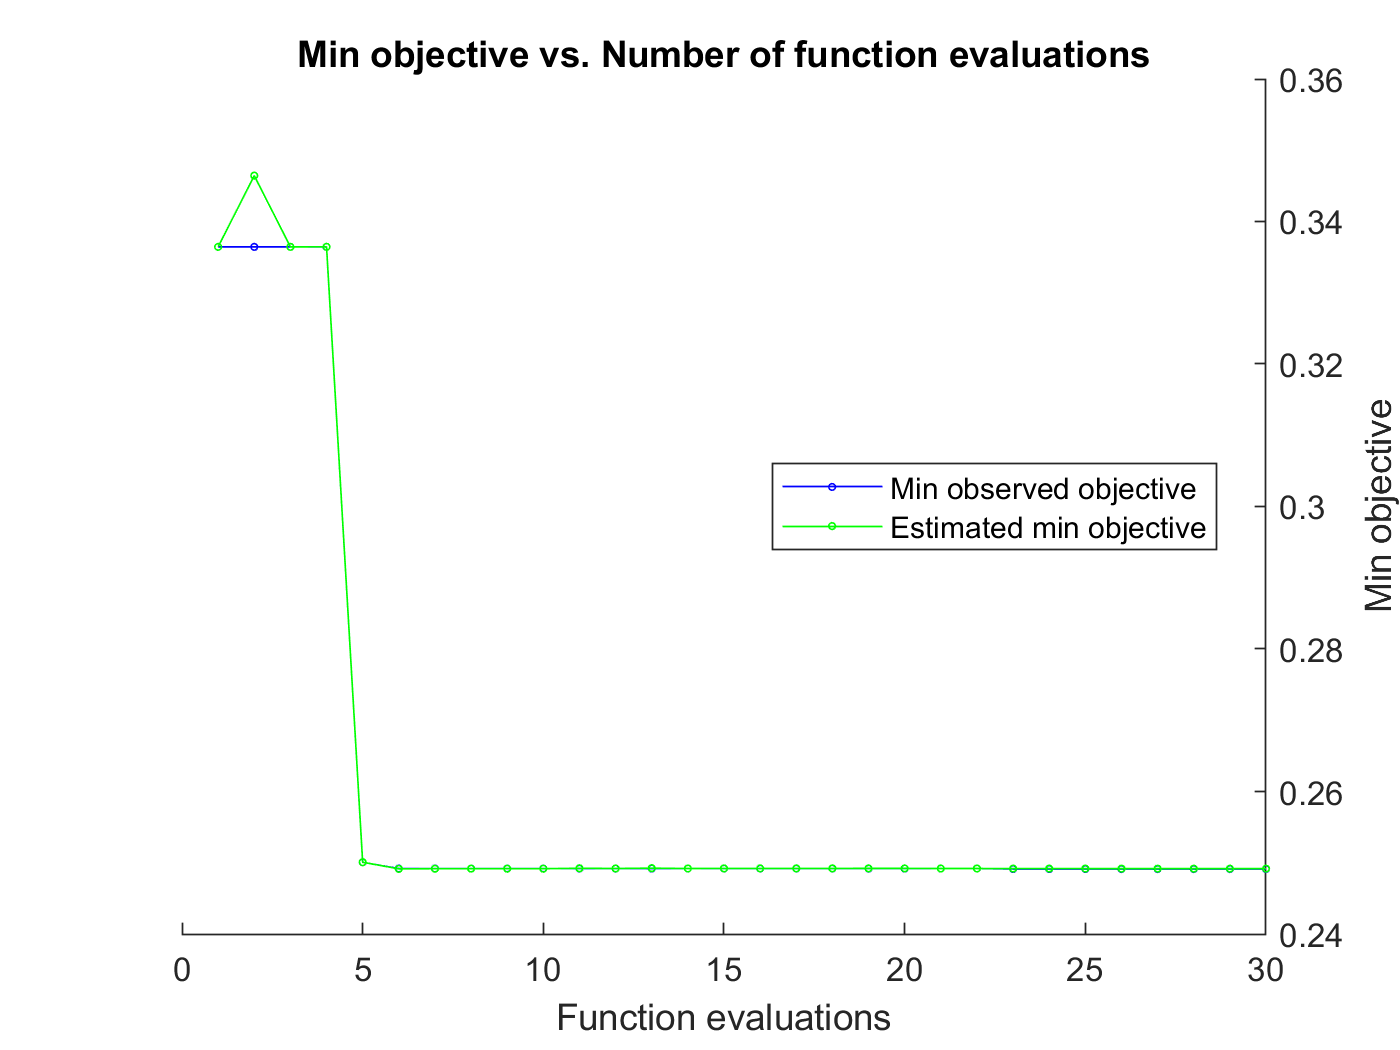

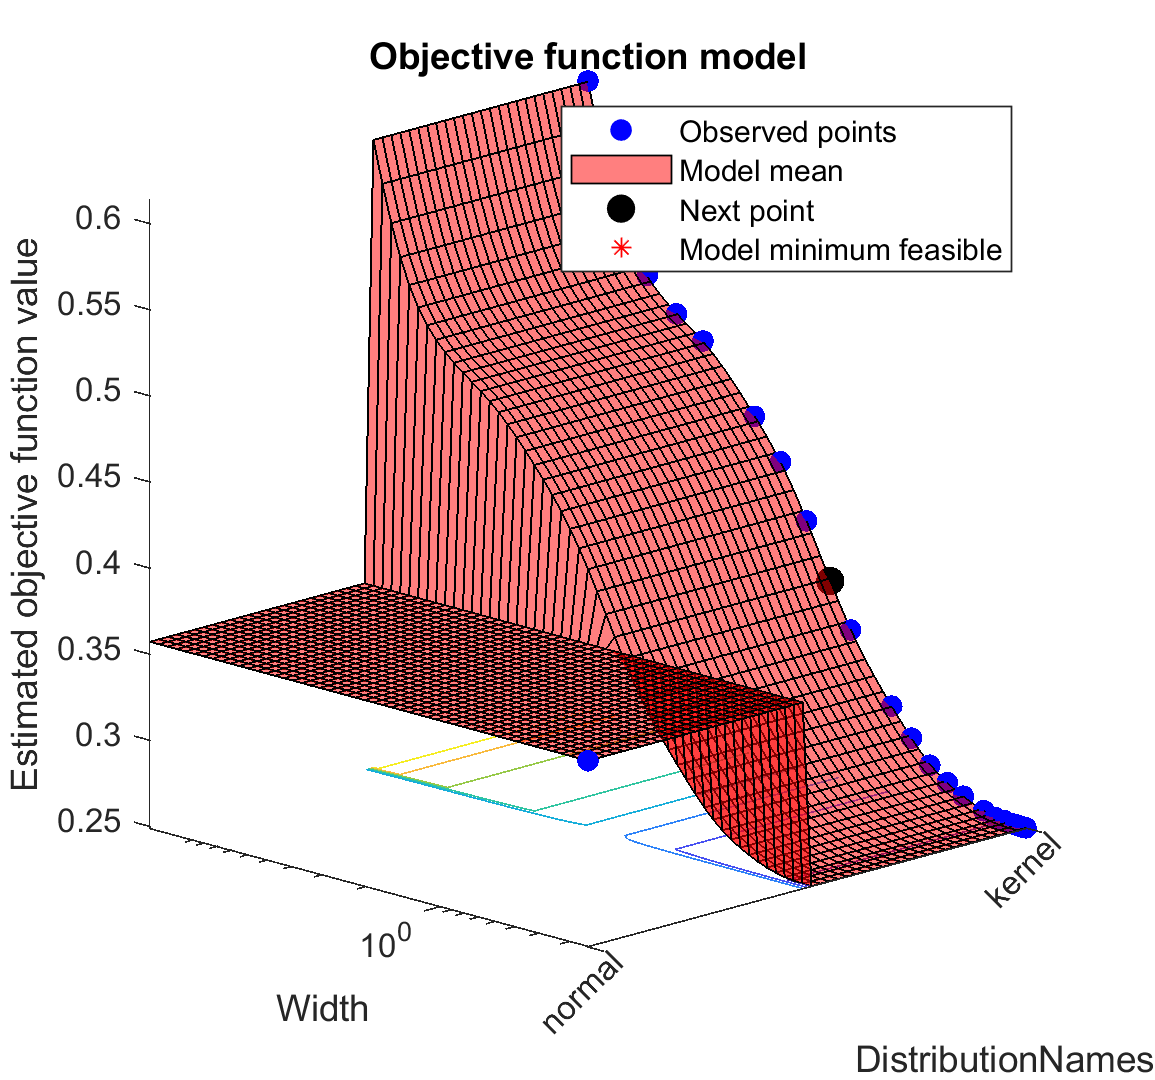


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 1593.3512 seconds
Total objective function evaluation time: 1558.1685

Best observed feasible point:
    DistributionNames     Width 
    _________________    _______

         kernel          0.25916

Observed objective function value = 0.24913
Estimated objective function value = 0.24917
Function evaluation time = 44.1343

Best estimated feasible point (according to models):
    DistributionNames     Width 
    _________________    _______

         kernel          0.25916

Estimated objective function value = 0.24917
Estimated function evaluation time = 44.07



letterDataset = letterDatasetNotNormalised;
[X, Y] = letterDataset.extractXYFromTable(letterDataset.trainTable);
X = table2array(X);
Y = table2array(Y);
nBayes = NBayesClass.getDefaultInstance(letterDataset);
% start timer
startTime = cputime;
nBayes.fitMatlabHyperparameterOptimization();

[trainingLoss, testLoss] = nBayes.getModelLoss();
endTime = cputime;
totalTime = endTime - startTime;
fprintf("Training loss: %0.04f Test loss: %0.04f, normalised dataset: %d\n", trainingLoss, testLoss, nBayes.dataset.isStandardised);

Training loss: 0.2339 Test loss: 0.2510, normalised dataset: 0


fprintf("Total cpu time (seconds, includes optimization search): %02.04f", totalTime);

Total cpu time (seconds): 7227.8594

disp(nBayes);

  NBayesClass with properties:

            randomSeed: 300
                 debug: 0
               dataset: [1×1 LetterDatasetClass]
           nBayesModel: [1×1 ClassificationNaiveBayes]
                     x: [16000×16 table]
                     y: [16000×1 table]
                    xt: [4000×16 table]
                    yt: [4000×1 table]
      distNamesDefault: {1×16 cell}
       distNamesKernel: {1×16 cell}
             smoothBox: {1×16 cell}
    smoothEpanechnikov: {1×16 cell}
           smootNormal: {1×16 cell}
        smoothTriangle: {1×16 cell}
         smoothUnsused: {1×16 cell}



### Try 'kernel' distribution on NOT Normalised dataset

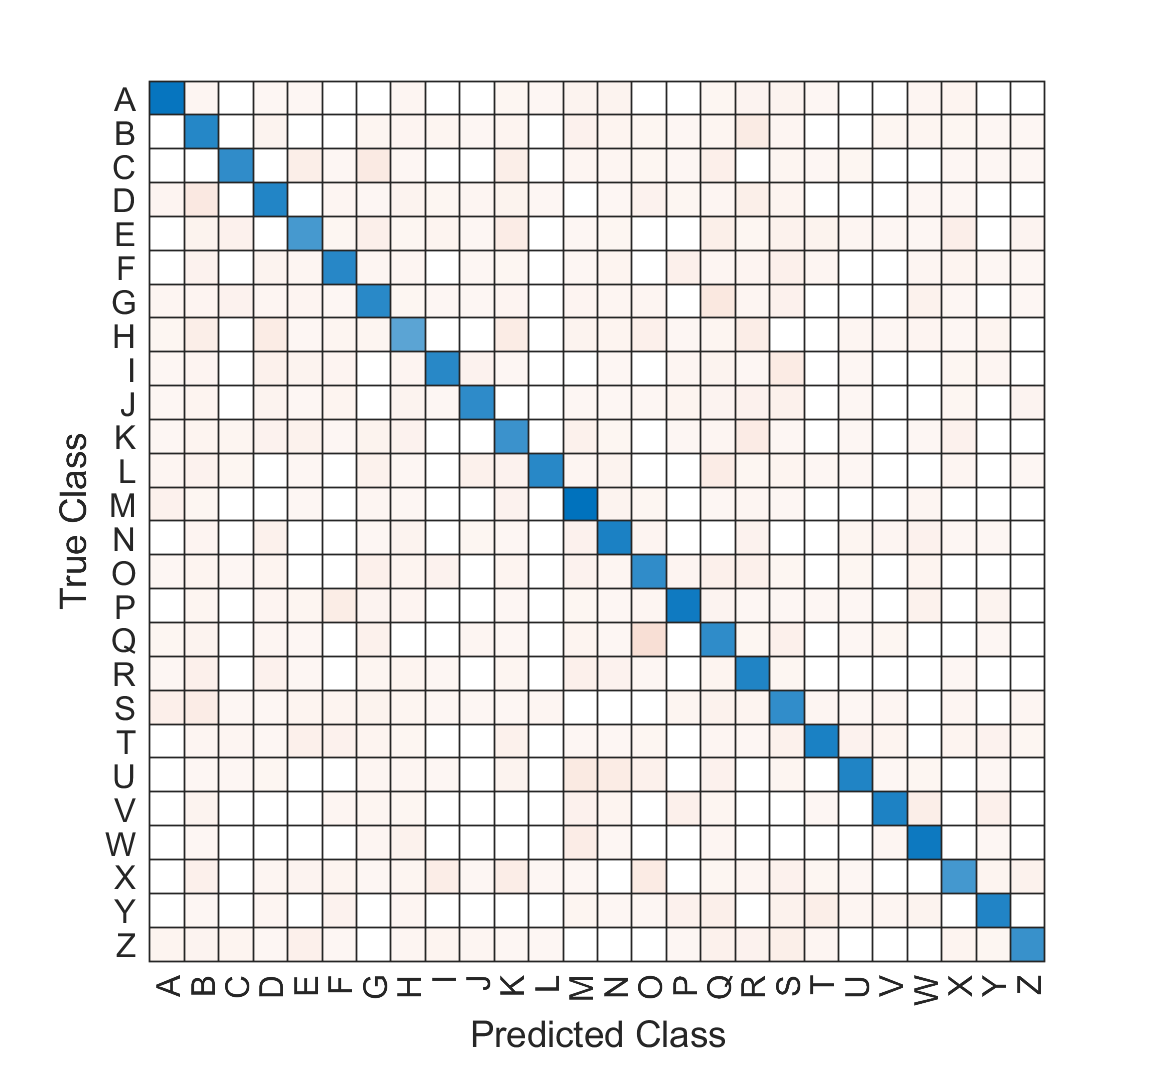

letterDataset = letterDatasetNotNormalised;
[X, Y] = letterDataset.extractXYFromTable(letterDataset.trainTable);
X = table2array(X);
Y = table2array(Y);
Bayes = NBayesClass.getKernelInstance(letterDataset);
model = nBayes.setPriorDistributionEmpirical();
% start timer
startTime = cputime;
predictions = resubPredict(model);
[trainingLoss, testLoss] = nBayes.getModelLoss();
endTime = cputime;
totalTime = endTime - startTime;
fig = figure;
confusionMat = confusionchart(categorical(Y), predictions,'RowSummary','row-normalized','ColumnSummary','column-normalized');
fig_Position = fig.Position;

fig_Position(3) = fig_Position(3)*1.5;
fig.Position = fig_Position;
fprintf("Training loss: %0.04f Test loss: %0.04f, normalised dataset: %d\n", trainingLoss, testLoss, nBayes.dataset.isStandardised);
fprintf("Total cpu time (seconds): %02.04f", totalTime);

Training loss: 0.2342 Test loss: 0.2508, normalised dataset: 0


disp(nBayes);

Total cpu time (seconds): 431.5938

#### Try Optimization

letterDataset = letterDatasetNotNormalised;

  NBayesClass with properties:

            randomSeed: 300
                 debug: 0
               dataset: [1×1 LetterDatasetClass]
           nBayesModel: [1×1 ClassificationNaiveBayes]
                     x: [16000×16 table]
                     y: [16000×1 table]
                    xt: [4000×16 table]
                    yt: [4000×1 table]
      distNamesDefault: {1×16 cell}
       distNamesKernel: {1×16 cell}
             smoothBox: {1×16 cell}
    smoothEpanechnikov: {1×16 cell}
           smootNormal: {1×16 cell}
        smoothTriangle: {1×16 cell}
         smoothUnsused: {1×16 cell}



|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |
|=====================================================================================================|
|    1 | Best   |     0.33644 |       72.58 |     0.33644 |     0.33644 |       kernel |        1.287 |


|    2 | Accept |     0.35725 |      0.4535 |     0.33644 |     0.34644 |       normal |            - |


|    3 | Accept |     0.35725 |     0.44834 |     0.33644 |     0.33644 |       normal |            - |


|    4 | Accept |     0.51019 |      70.984 |     0.33644 |     0.33644 |       kernel |       8.6162 |


|    5 | Best   |     0.25006 |       44.24 |     0.25006 |     0.25007 |       kernel |      0.30805 |


|    6 | Best   |     0.24919 |      44.295 |     0.24919 |     0.24914 |       kernel |      0.25009 |


|    7 | Accept |     0.24919 |      44.134 |     0.24919 |     0.24916 |       kernel |      0.25013 |


|    8 | Accept |     0.24919 |      44.312 |     0.24919 |     0.24917 |       kernel |      0.25022 |


|    9 | Accept |     0.24919 |      44.229 |     0.24919 |     0.24917 |       kernel |      0.26337 |


|   10 | Accept |     0.24919 |      44.177 |     0.24919 |     0.24917 |       kernel |      0.25043 |


|   11 | Accept |     0.27044 |      57.327 |     0.24919 |     0.24922 |       kernel |      0.61428 |


|   12 | Accept |     0.61375 |      70.342 |     0.24919 |      0.2492 |       kernel |       14.998 |


|   13 | Accept |     0.24938 |      44.191 |     0.24919 |     0.24924 |       kernel |      0.27578 |


|   14 | Accept |     0.44525 |      73.877 |     0.24919 |     0.24919 |       kernel |       3.1633 |


|   15 | Accept |     0.24931 |       44.46 |     0.24919 |      0.2492 |       kernel |      0.26992 |


|   16 | Accept |     0.25769 |      44.358 |     0.24919 |     0.24921 |       kernel |      0.44953 |


|   17 | Accept |     0.29875 |      65.078 |     0.24919 |     0.24921 |       kernel |      0.87686 |


|   18 | Accept |     0.48094 |      71.914 |     0.24919 |     0.24921 |       kernel |       5.1232 |


|   19 | Accept |      0.2525 |      44.436 |     0.24919 |     0.24921 |       kernel |      0.37089 |


|   20 | Accept |     0.39281 |      74.655 |     0.24919 |     0.24921 |       kernel |       1.9431 |


|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |
|=====================================================================================================|
|   21 | Accept |     0.25031 |      44.215 |     0.24919 |     0.24919 |       kernel |      0.33501 |


|   22 | Accept |     0.26306 |      57.454 |     0.24919 |     0.24919 |       kernel |      0.52137 |


|   23 | Best   |     0.24913 |      44.195 |     0.24913 |     0.24918 |       kernel |      0.25916 |


|   24 | Accept |     0.24944 |      44.153 |     0.24913 |     0.24918 |       kernel |      0.28773 |


|   25 | Accept |     0.24913 |      44.152 |     0.24913 |     0.24918 |       kernel |      0.25891 |


|   26 | Accept |     0.24913 |      44.165 |     0.24913 |     0.24917 |       kernel |       0.2586 |


|   27 | Accept |     0.54869 |      70.562 |     0.24913 |     0.24917 |       kernel |       11.674 |


|   28 | Accept |     0.28331 |       56.39 |     0.24913 |     0.24917 |       kernel |      0.72876 |


|   29 | Accept |       0.423 |      74.245 |     0.24913 |     0.24917 |       kernel |       2.4778 |


|   30 | Accept |      0.4925 |      71.715 |     0.24913 |     0.24917 |       kernel |       6.5632 |



__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 1581.3599 seconds
Total objective function evaluation time: 1551.7347

Best observed feasible point:
    DistributionNames     Width 
    _________________    _______

         kernel          0.25916

Observed objective function value = 0.24913
Estimated objective function value = 0.24917
Function evaluation time = 44.1947

Best estimated feasible point (according to models):
    DistributionNames     Width 
    _________________    _______

         kernel          0.25916

Estimated objective function value = 0.24917
Estimated function evaluation time = 43.9913



[X, Y] = letterDataset.extractXYFromTable(letterDataset.trainTable);
X = table2array(X);
Y = table2array(Y);
nBayes = NBayesClass(letterDataset);
% start timer
startTime = cputime
nBayes.fitMatlabHyperparameterOptimization();
predictions = resubPredict(nBayes.nBayesModel);
[trainingLoss, testLoss] = nBayes.getModelLoss();
endTime = cputime;

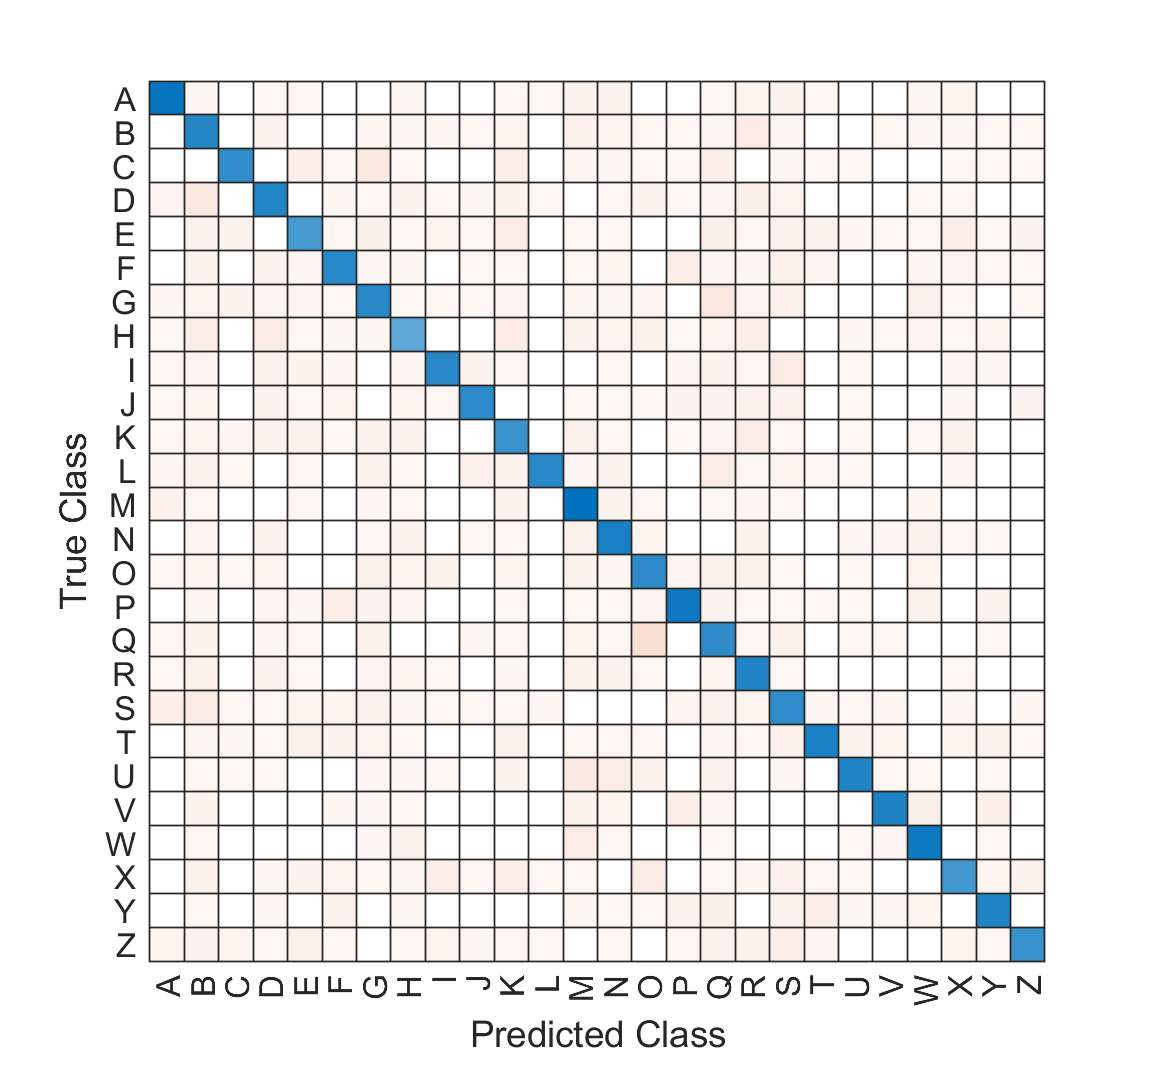

totalTime = endTime - startTime;
fig = figure;
confusionMat = confusionchart(categorical(Y), predictions,'RowSummary','row-normalized','ColumnSummary','column-normalized');
fig_Position = fig.Position;
fig_Position(3) = fig_Position(3)*1.5;
fig.Position = fig_Position;

fprintf("Training loss: %0.04f Test loss: %0.04f, normalised dataset: %d\n", trainingLoss, testLoss, nBayes.dataset.isStandardised);
fprintf("Total cpu time (seconds, includes optimization search): %02.04f", totalTime);
disp(nBayes);

### Try Normalised Dataset

clear

Training loss: 0.2339 Test loss: 0.2510, normalised dataset: 0


clc

Total cpu time (seconds): 7387.9531

clf

  NBayesClass with properties:

            randomSeed: 300
                 debug: 0
               dataset: [1×1 LetterDatasetClass]
           nBayesModel: [1×1 ClassificationNaiveBayes]
                     x: [16000×16 table]
                     y: [16000×1 table]
                    xt: [4000×16 table]
                    yt: [4000×1 table]
      distNamesDefault: {1×16 cell}
       distNamesKernel: {1×16 cell}
             smoothBox: {1×16 cell}
    smoothEpanechnikov: {1×16 cell}
           smootNormal: {1×16 cell}
        smoothTriangle: {1×16 cell}
         smoothUnsused: {1×16 cell}



close all
% loads the letter dataset 
% 
load letterDatasetClass.mat
letterDataset = letterDatasetStandardised;
[X, Y] = letterDataset.extractXYFromTable(letterDataset.trainTable);
X = table2array(X);
Y = table2array(Y);

% get a kernel class
nBayes = NBayesClass.getDefaultInstance(letterDataset);
model = nBayes.setPriorDistributionEmpirical();
% start timer
startTime = cputime;
predictions = resubPredict(model);
[trainingLoss, testLoss] = nBayes.getModelLoss();
endTime = cputime;
totalTime = endTime - startTime;
confusionMat = confusionchart(categorical(Y), predictions,'RowSummary','row-normalized','ColumnSummary','column-normalized');
fig_Position = fig.Position;
fig_Position(3) = fig_Position(3)*1.5;
fig.Position = fig_Position;


fprintf("Training loss: %0.04f Test loss: %0.04f, normalised dataset: %d\n", ...
    trainingLoss, testLoss, nBayes.dataset.isStandardised);
fprintf("Total cpu time (seconds): %02.04f", totalTime);

Training loss: 0.3549 Test loss: 0.3678, normalised dataset: 1


disp(nBayes);

Total cpu time (seconds): 1.7031

#### Try Optimization (MATLab sets distribution to Kernel, normal (gaussian)

letterDataset = letterDatasetStandardised;

  NBayesClass with properties:

            randomSeed: 300
                 debug: 0
               dataset: [1×1 LetterDatasetClass]
           nBayesModel: [1×1 ClassificationNaiveBayes]
                     x: [16000×16 table]
                     y: [16000×1 table]
                    xt: [4000×16 table]
                    yt: [4000×1 table]
      distNamesDefault: {1×16 cell}
       distNamesKernel: {1×16 cell}
             smoothBox: {1×16 cell}
    smoothEpanechnikov: {1×16 cell}
           smootNormal: {1×16 cell}
        smoothTriangle: {1×16 cell}
         smoothUnsused: {1×16 cell}



[X, Y] = letterDataset.extractXYFromTable(letterDataset.trainTable);
X = table2array(X);
Y = table2array(Y);

startTime = 1.5124e+04

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |
|=====================================================================================================|
|    1 | Best   |     0.33375 |      72.328 |     0.33375 |     0.33375 |       kernel |       0.5295 |


|    2 | Accept |     0.35725 |     0.45575 |     0.33375 |     0.34505 |       normal |            - |


|    3 | Accept |     0.35725 |     0.45256 |     0.33375 |     0.33375 |       normal |            - |


|    4 | Accept |       0.544 |      71.616 |     0.33375 |     0.33376 |       kernel |       5.0418 |


|    5 | Best   |      0.2495 |      28.456 |      0.2495 |     0.24951 |       kernel |     0.097246 |


|    6 | Accept |     0.25506 |      44.879 |      0.2495 |     0.24948 |       kernel |      0.16486 |


|    7 | Accept |      0.2495 |      26.319 |      0.2495 |     0.24922 |       kernel |     0.075972 |


|    8 | Accept |     0.24963 |      29.611 |      0.2495 |     0.24941 |       kernel |     0.097976 |


|    9 | Accept |      0.2495 |      26.406 |      0.2495 |     0.24941 |       kernel |     0.075985 |


|   10 | Accept |      0.2495 |      26.349 |      0.2495 |     0.24941 |       kernel |     0.092949 |


|   11 | Accept |     0.24956 |       26.33 |      0.2495 |     0.24943 |       kernel |     0.090648 |


|   12 | Accept |      0.2495 |      26.418 |      0.2495 |     0.24943 |       kernel |     0.075988 |


|   13 | Accept |     0.74075 |      70.732 |      0.2495 |      0.2495 |       kernel |       9.7236 |


|   14 | Accept |     0.25006 |      37.407 |      0.2495 |     0.24949 |       kernel |      0.12165 |


|   15 | Accept |      0.2495 |      26.442 |      0.2495 |     0.24949 |       kernel |     0.085342 |


|   16 | Accept |     0.24994 |      34.039 |      0.2495 |     0.24952 |       kernel |      0.10978 |


|   17 | Accept |      0.2495 |      26.331 |      0.2495 |     0.24952 |       kernel |     0.076067 |


|   18 | Accept |     0.46381 |      73.474 |      0.2495 |     0.24952 |       kernel |       1.5736 |


|   19 | Accept |      0.2495 |      26.329 |      0.2495 |      0.2495 |       kernel |     0.084293 |


|   20 | Accept |     0.28288 |      59.502 |      0.2495 |      0.2495 |       kernel |      0.31036 |


|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |
|=====================================================================================================|
|   21 | Accept |     0.49988 |      71.362 |      0.2495 |      0.2495 |       kernel |       2.7621 |


|   22 | Accept |     0.39544 |      75.536 |      0.2495 |     0.24947 |       kernel |      0.87436 |


|   23 | Accept |     0.26456 |      51.221 |      0.2495 |     0.24947 |       kernel |      0.22589 |


|   24 | Accept |      0.2515 |       41.38 |      0.2495 |     0.24948 |       kernel |      0.14167 |


|   25 | Accept |     0.30419 |      66.319 |      0.2495 |     0.24948 |       kernel |      0.39711 |


|   26 | Accept |     0.25988 |      46.379 |      0.2495 |     0.24949 |       kernel |      0.19193 |


|   27 | Accept |      0.2495 |       26.31 |      0.2495 |     0.24949 |       kernel |     0.079753 |


|   28 | Accept |     0.25056 |      40.051 |      0.2495 |      0.2495 |       kernel |      0.13008 |


|   29 | Accept |     0.24988 |      30.571 |      0.2495 |     0.24949 |       kernel |      0.10335 |


|   30 | Accept |      0.2495 |      26.306 |      0.2495 |     0.24949 |       kernel |     0.079577 |


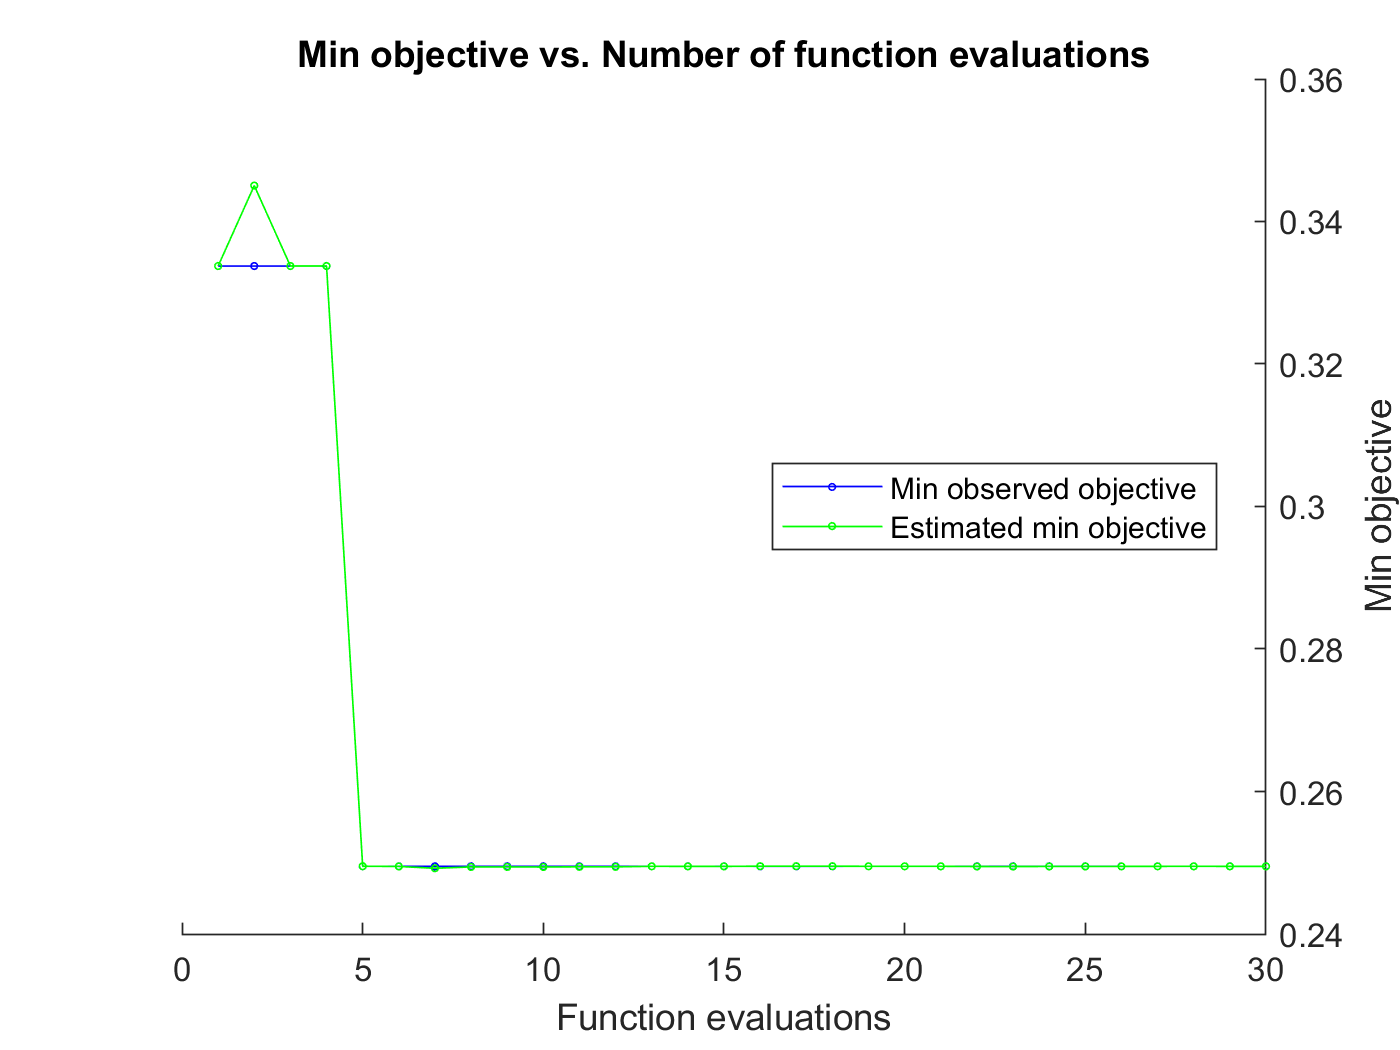

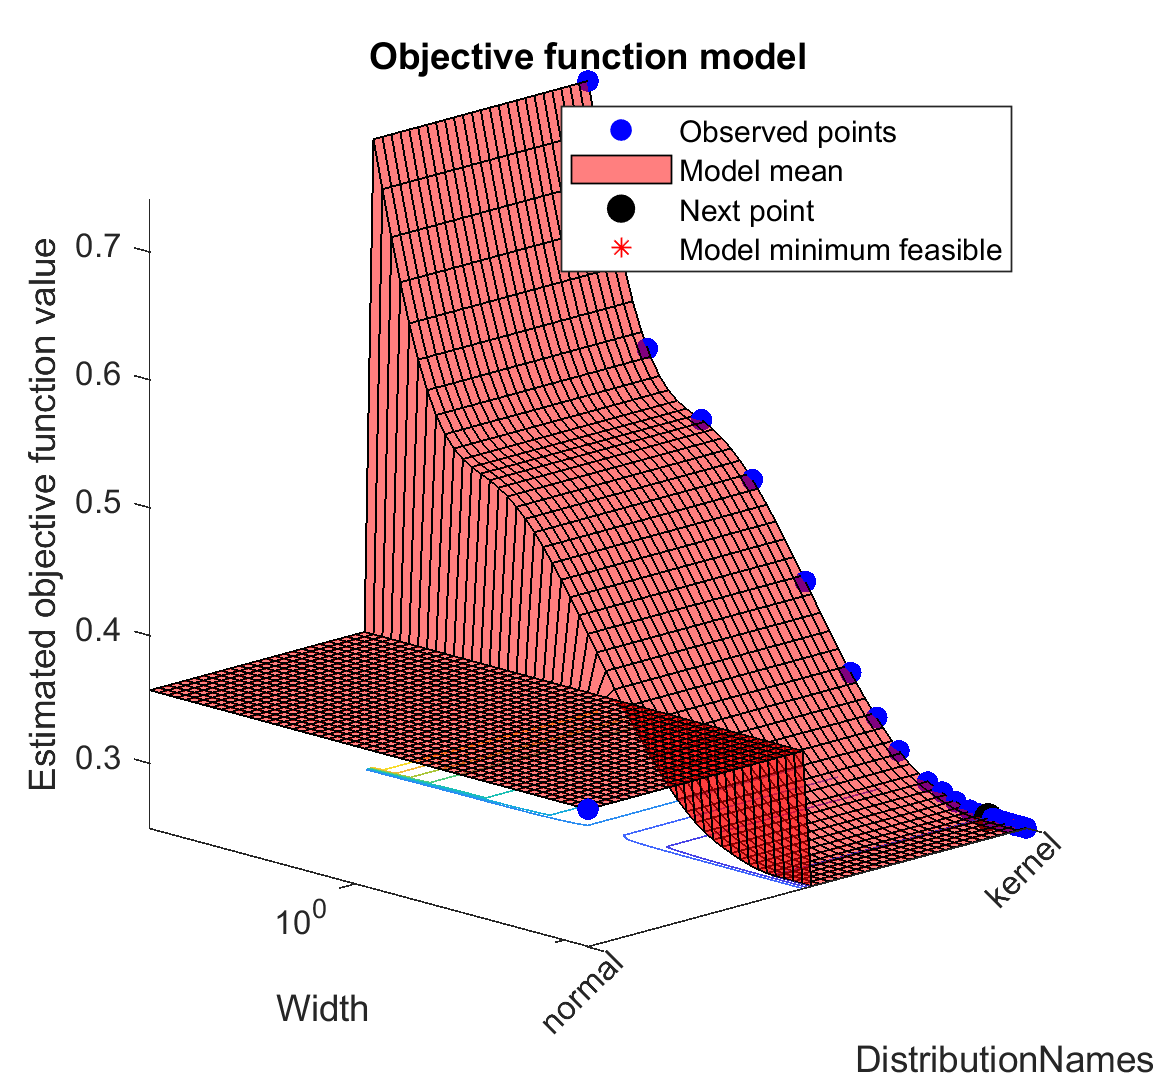


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 1236.7003 seconds
Total objective function evaluation time: 1209.31

Best observed feasible point:
    DistributionNames     Width  
    _________________    ________

         kernel          0.097246

Observed objective function value = 0.2495
Estimated objective function value = 0.24959
Function evaluation time = 28.4555

Best estimated feasible point (according to models):
    DistributionNames     Width  
    _________________    ________

         kernel          0.079577

Estimated objective function value = 0.24949
Estimated function evaluation time = 26.1106



nBayes = NBayesClass(letterDataset);
% start timer
startTime = cputime
nBayes.fitMatlabHyperparameterOptimization();
predictions = resubPredict(nBayes.nBayesModel);
[trainingLoss, testLoss] = nBayes.getModelLoss();
endTime = cputime;

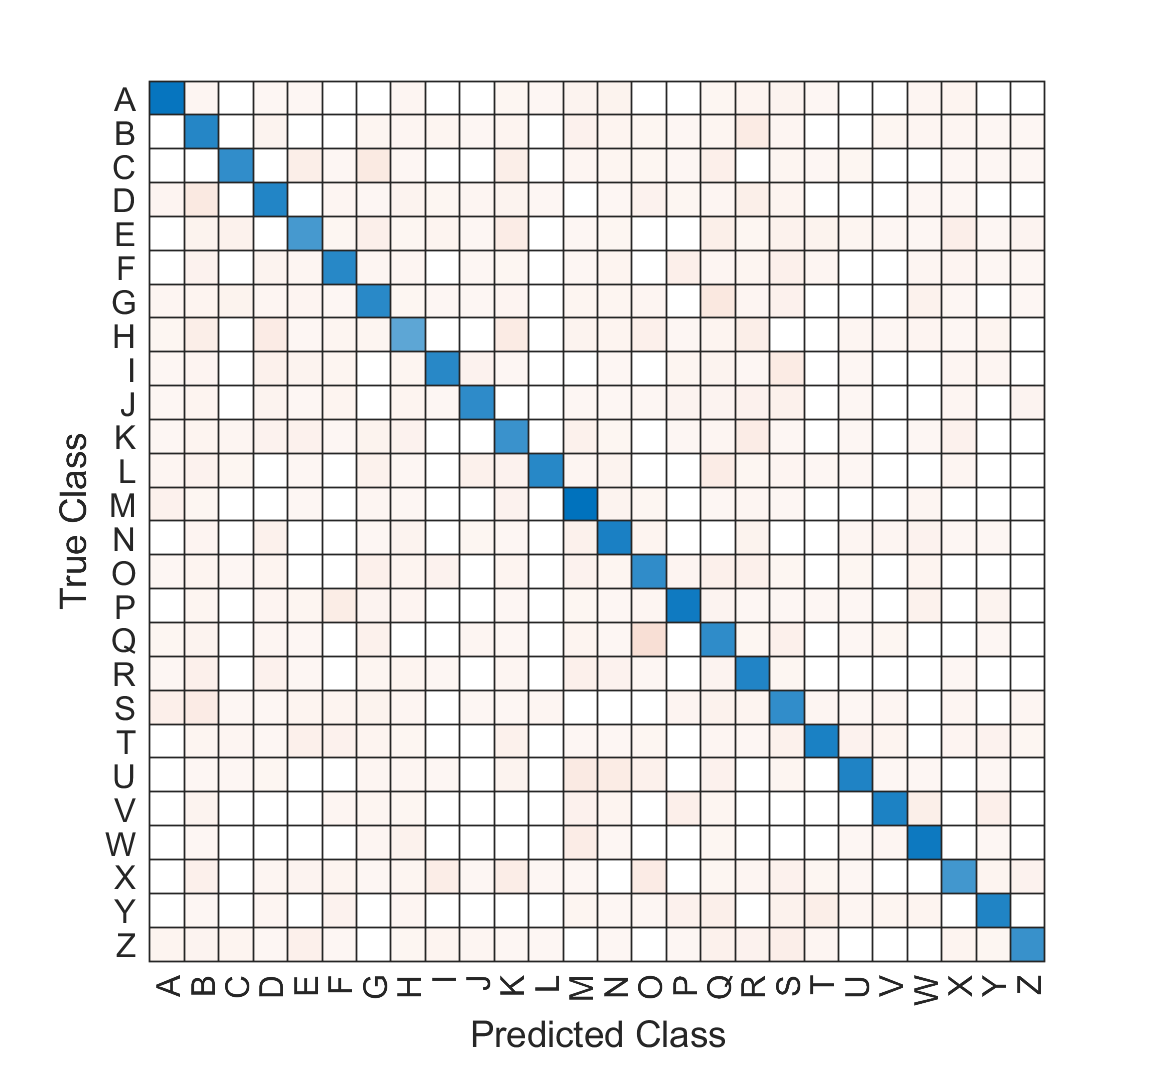

Training loss: 0.2336 Test loss: 0.2525, normalised dataset: 1


totalTime = endTime - startTime;
confusionMat = confusionchart(categorical(Y), predictions,'RowSummary','row-normalized','ColumnSummary','column-normalized');
fig_Position = fig.Position;
fig_Position(3) = fig_Position(3)*1.5;
fig.Position = fig_Position;
fprintf("Training loss: %0.04f Test loss: %0.04f, normalised dataset: %d\n", trainingLoss, testLoss, nBayes.dataset.isStandardised);
fprintf("Total cpu time (seconds, includes optimization search): %02.04f", totalTime);
disp(nBayes);

### Try 'kernel' distribution on Normalised dataset

clear

Total cpu time (seconds): 4700.1563

clc

  NBayesClass with properties:

            randomSeed: 300
                 debug: 0
               dataset: [1×1 LetterDatasetClass]
           nBayesModel: [1×1 ClassificationNaiveBayes]
                     x: [16000×16 table]
                     y: [16000×1 table]
                    xt: [4000×16 table]
                    yt: [4000×1 table]
      distNamesDefault: {1×16 cell}
       distNamesKernel: {1×16 cell}
             smoothBox: {1×16 cell}
    smoothEpanechnikov: {1×16 cell}
           smootNormal: {1×16 cell}
        smoothTriangle: {1×16 cell}
         smoothUnsused: {1×16 cell}



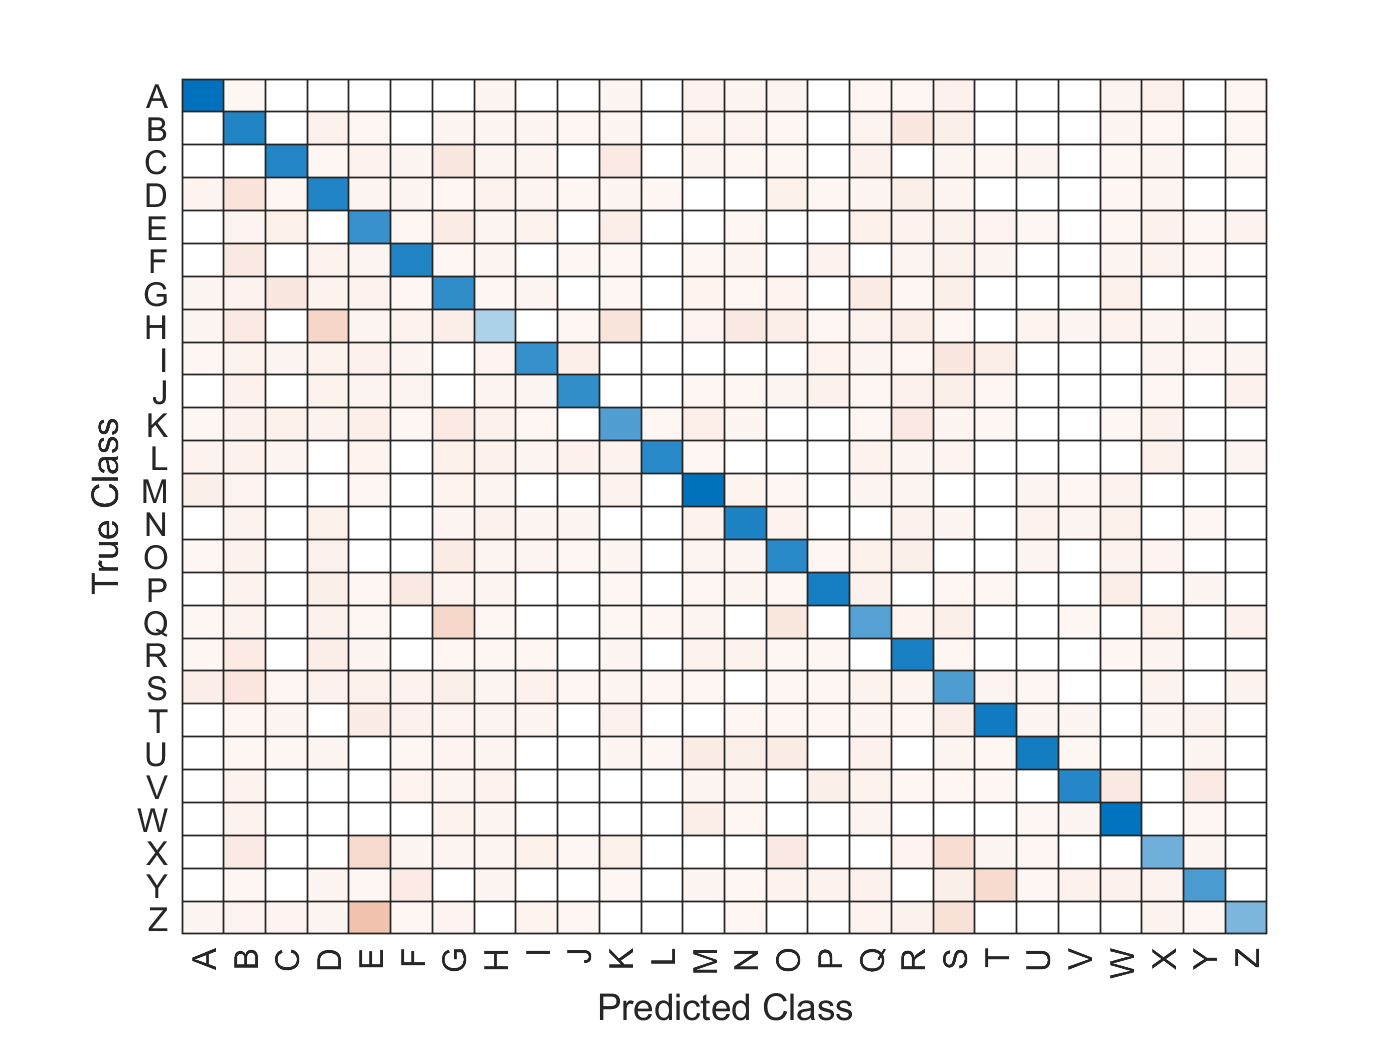

clf
close all
% loads the letter dataset 
% 
load letterDatasetClass.mat
letterDataset = letterDatasetStandardised;
[X, Y] = letterDataset.extractXYFromTable(letterDataset.trainTable);
X = table2array(X);
Y = table2array(Y);

% get a kernel class
nBayes = NBayesClass.getKernelInstance(letterDataset);
model = nBayes.setPriorDistributionEmpirical();
startTime = cputime;
predictions = resubPredict(model);

[trainingLoss, testLoss] = nBayes.getModelLoss();
endTime = cputime;
totalTime = endTime - startTime;
confusionMat = confusionchart(categorical(Y), predictions,'RowSummary','row-normalized','ColumnSummary','column-normalized');

fig_Position = fig.Position;
fig_Position(3) = fig_Position(3)*1.5;
fig.Position = fig_Position;

fprintf("Training loss: %0.04f Test loss: %0.04f, normalised dataset: %d\n", ...
    trainingLoss, testLoss, nBayes.dataset.isStandardised);
fprintf("Total cpu time (seconds): %02.04f", totalTime);
disp(nBayes);

### Try Reduced Attribute Standardised Dataset Test Run

A final normalised, kernel run is performed on the **dataset with the highly correlated features removed.**

clear
clc
clf

Training loss: 0.3040 Test loss: 0.3213, normalised dataset: 1


close all

Total cpu time (seconds): 601.5625

% loads the letter dataset 

  NBayesClass with properties:

            randomSeed: 300
                 debug: 0
               dataset: [1×1 LetterDatasetClass]
           nBayesModel: [1×1 ClassificationNaiveBayes]
                     x: [16000×16 table]
                     y: [16000×1 table]
                    xt: [4000×16 table]
                    yt: [4000×1 table]
      distNamesDefault: {1×16 cell}
       distNamesKernel: {1×16 cell}
             smoothBox: {1×16 cell}
    smoothEpanechnikov: {1×16 cell}
           smootNormal: {1×16 cell}
        smoothTriangle: {1×16 cell}
         smoothUnsused: {1×16 cell}



% 
load letterDatasetClass.mat
letterDataset = letterDatasetStandardised;
letterDataset.removeColumn("xBox");
letterDataset.removeColumn("yBox");
letterDataset.removeColumn("width");
letterDataset.removeColumn("height");
[X, Y] = letterDataset.extractXYFromTable(letterDataset.trainTable);
X = table2array(X);
Y = table2array(Y);

% get a kernel class
nBayes = NBayesClass.getKernelInstance(letterDataset);
model = nBayes.setPriorDistributionEmpirical();
startTime = cputime;
predictions = resubPredict(model);
[trainingLoss, testLoss] = nBayes.getModelLoss();
endTime = cputime;
totalTime = endTime - startTime;
confusionMat = confusionchart(categorical(Y), predictions,'RowSummary','row-normalized','ColumnSummary','column-normalized');
fig_Position = fig.Position;
fig_Position(3) = fig_Position(3)*1.5;
fig.Position = fig_Position;

fprintf("Training loss: %0.04f Test loss: %0.04f, standardised dataset: %d\n", ...
    trainingLoss, testLoss, nBayes.dataset.isStandardised);
fprintf("Total cpu time (seconds): %02.04f", totalTime);
disp(nBayes);

#### Try Optimization (uses letterDataset defined in previous cell)

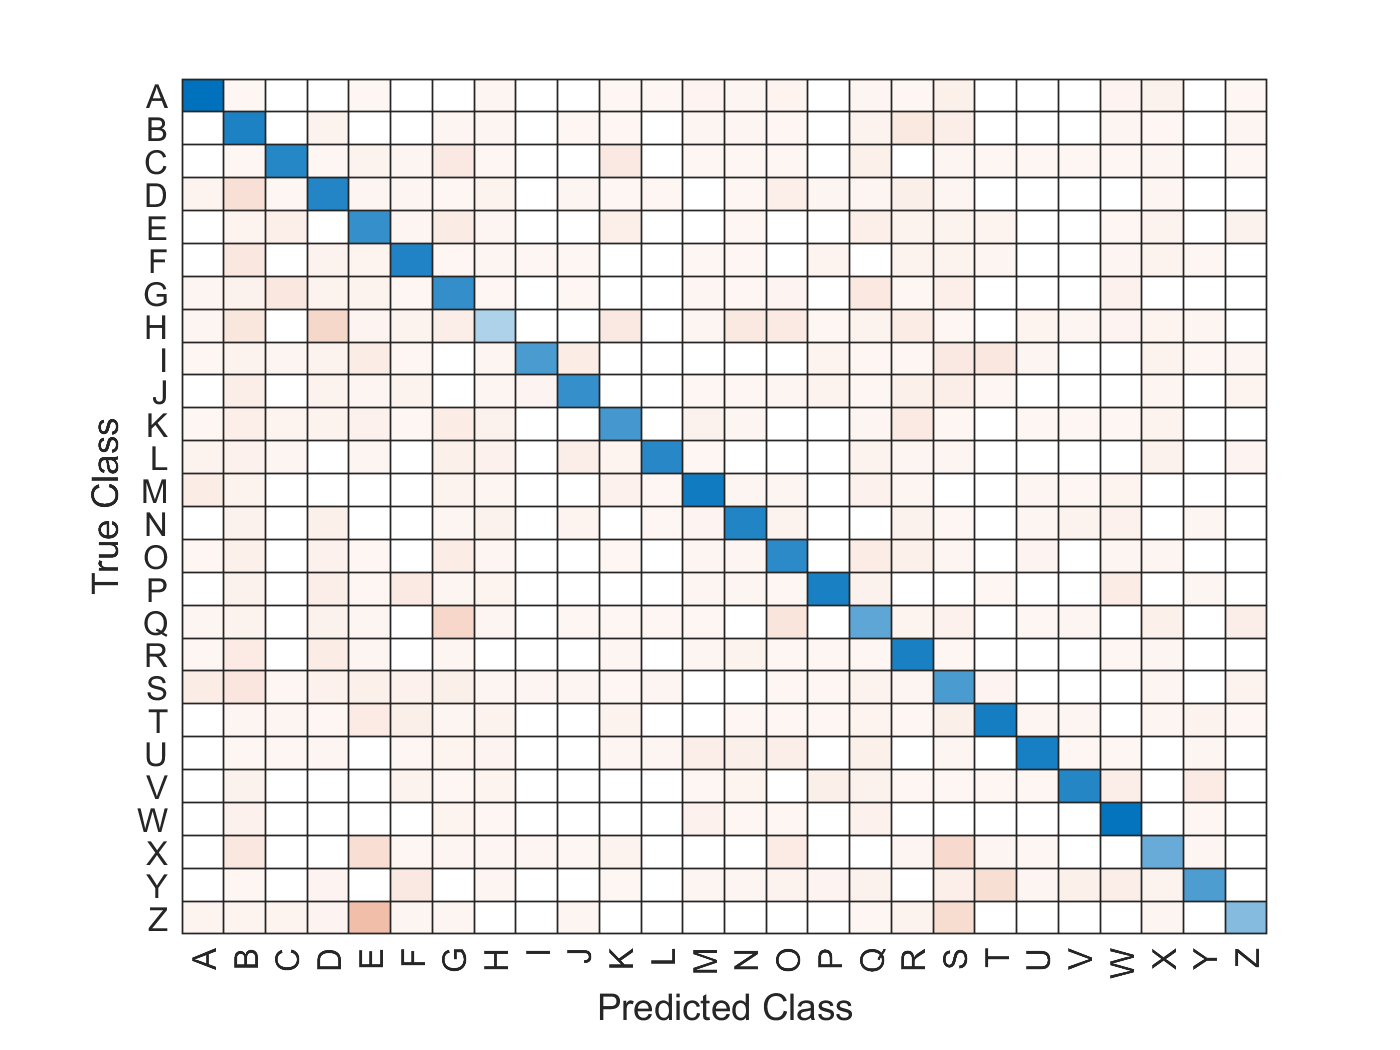

nBayes = NBayesClass.getKernelInstance(letterDataset);

startTime = cputime;
nBayes.fitMatlabHyperparameterOptimization();
predictions = resubPredict(nBayes.nBayesModel);

Training loss: 0.3059 Test loss: 0.3123, standardised dataset: 1


[trainingLoss, testLoss] = nBayes.getModelLoss();

Total cpu time (seconds): 441.8594

endTime = cputime;

  NBayesClass with properties:

            randomSeed: 300
                 debug: 0
               dataset: [1×1 LetterDatasetClass]
           nBayesModel: [1×1 ClassificationNaiveBayes]
                     x: [16000×12 table]
                     y: [16000×1 table]
                    xt: [4000×12 table]
                    yt: [4000×1 table]
      distNamesDefault: {1×12 cell}
       distNamesKernel: {1×12 cell}
             smoothBox: {'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'}
    smoothEpanechnikov: {1×12 cell}
           smootNormal: {1×12 cell}
        smoothTriangle: {1×12 cell}
         smoothUnsused: {1×16 cell}



|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |
|=====================================================================================================|
|    1 | Best   |     0.33531 |      54.267 |     0.33531 |     0.33531 |       kernel |      0.59875 |


|    2 | Accept |       0.347 |     0.41661 |     0.33531 |     0.34093 |       normal |            - |


|    3 | Accept |       0.347 |     0.41454 |     0.33531 |     0.33531 |       normal |            - |


|    4 | Accept |     0.54338 |      53.137 |     0.33531 |     0.33532 |       kernel |       5.1836 |


|    5 | Best   |     0.24844 |      20.506 |     0.24844 |     0.24845 |       kernel |       0.0932 |


|    6 | Accept |     0.24844 |       21.56 |     0.24844 |     0.24842 |       kernel |     0.096024 |


|    7 | Accept |     0.25038 |       30.74 |     0.24844 |     0.24831 |       kernel |      0.15132 |


|    8 | Accept |     0.24863 |      28.155 |     0.24844 |     0.24845 |       kernel |       0.1144 |


|    9 | Accept |     0.24856 |      27.049 |     0.24844 |     0.24836 |       kernel |      0.11119 |


|   10 | Accept |     0.24863 |      27.064 |     0.24844 |     0.24842 |       kernel |      0.10965 |


|   11 | Accept |     0.24844 |      20.354 |     0.24844 |     0.24842 |       kernel |     0.093284 |


|   12 | Accept |     0.75038 |      53.678 |     0.24844 |     0.24845 |       kernel |       9.7261 |


|   13 | Accept |     0.26088 |      39.585 |     0.24844 |     0.24842 |       kernel |       0.2395 |


|   14 | Accept |     0.24844 |      20.524 |     0.24844 |     0.24842 |       kernel |     0.093226 |


|   15 | Accept |     0.24844 |      20.495 |     0.24844 |     0.24842 |       kernel |     0.093274 |


|   16 | Accept |     0.45938 |      56.368 |     0.24844 |     0.24841 |       kernel |       1.7272 |


|   17 | Accept |      0.2485 |      23.559 |     0.24844 |     0.24842 |       kernel |      0.10246 |


|   18 | Accept |     0.29025 |      48.439 |     0.24844 |     0.24842 |       kernel |      0.38198 |


|   19 | Accept |     0.49269 |      53.717 |     0.24844 |     0.24843 |       kernel |       2.9322 |


|   20 | Accept |      0.3965 |      56.365 |     0.24844 |     0.24843 |       kernel |      0.98065 |


|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |
|=====================================================================================================|
|   21 | Accept |     0.25525 |      35.057 |     0.24844 |     0.24844 |       kernel |      0.19066 |


|   22 | Accept |     0.27113 |      42.615 |     0.24844 |     0.24844 |       kernel |      0.29783 |


|   23 | Accept |     0.24925 |       30.84 |     0.24844 |     0.24844 |       kernel |      0.13231 |


|   24 | Accept |     0.25194 |       33.63 |     0.24844 |     0.24844 |       kernel |      0.16807 |


|   25 | Accept |     0.24844 |      29.419 |     0.24844 |     0.24844 |       kernel |      0.12221 |


|   26 | Accept |     0.24844 |      22.644 |     0.24844 |     0.24843 |       kernel |     0.098351 |


|   27 | Accept |     0.24863 |      28.331 |     0.24844 |     0.24843 |       kernel |      0.12018 |


|   28 | Accept |      0.3125 |      51.486 |     0.24844 |     0.24844 |       kernel |      0.47467 |


|   29 | Accept |      0.2485 |        23.7 |     0.24844 |     0.24844 |       kernel |      0.10455 |


|   30 | Accept |        0.25 |      30.789 |     0.24844 |     0.24843 |       kernel |       0.1404 |


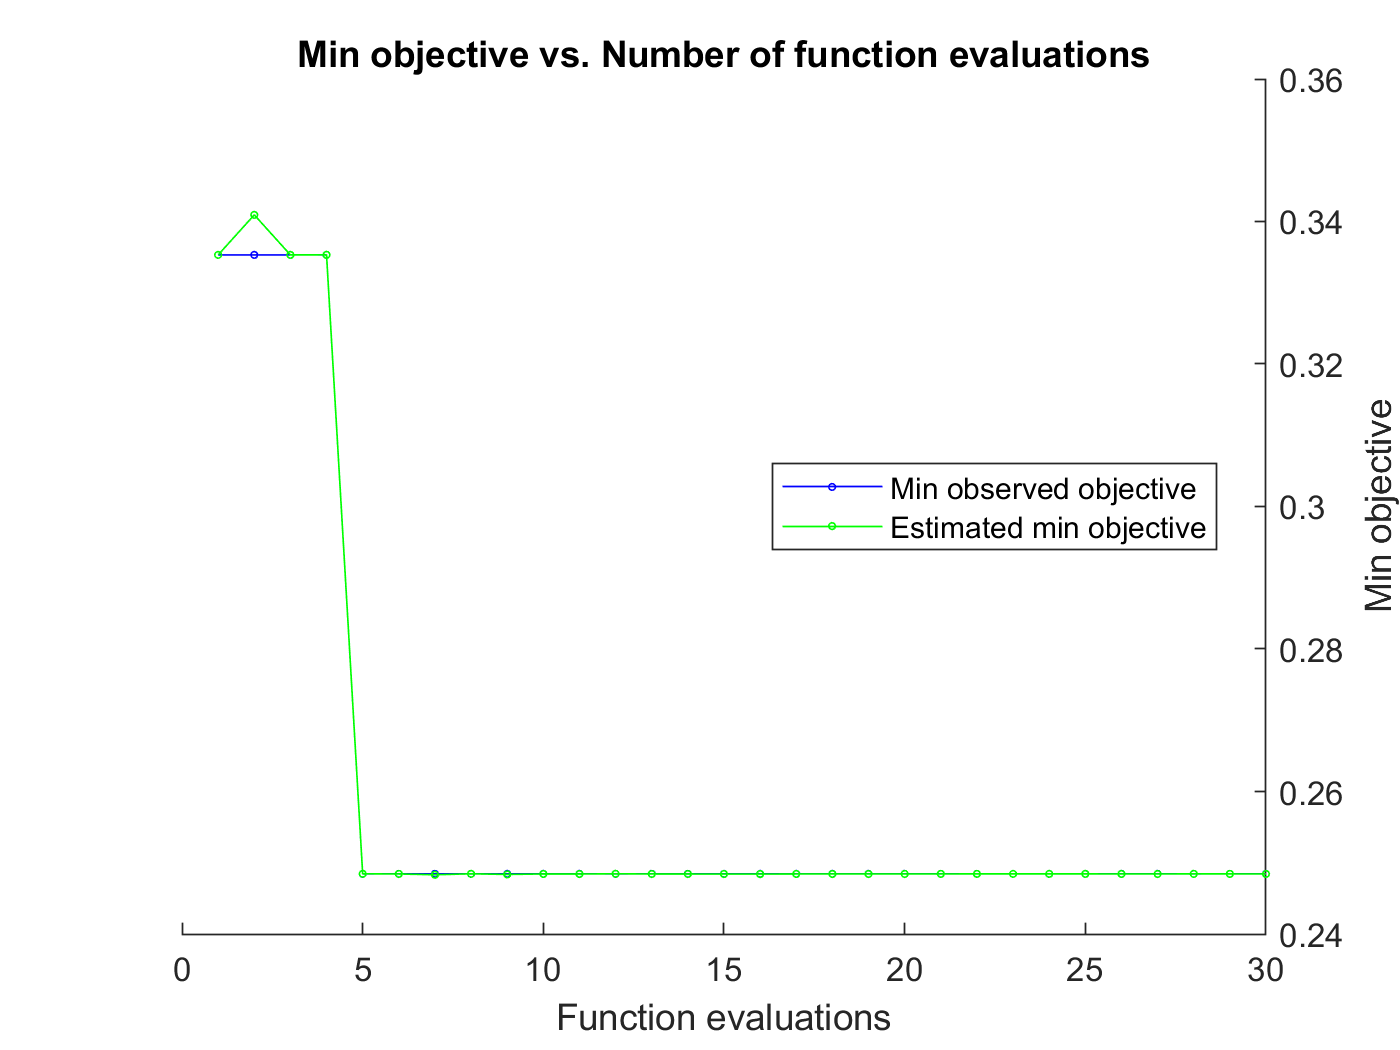

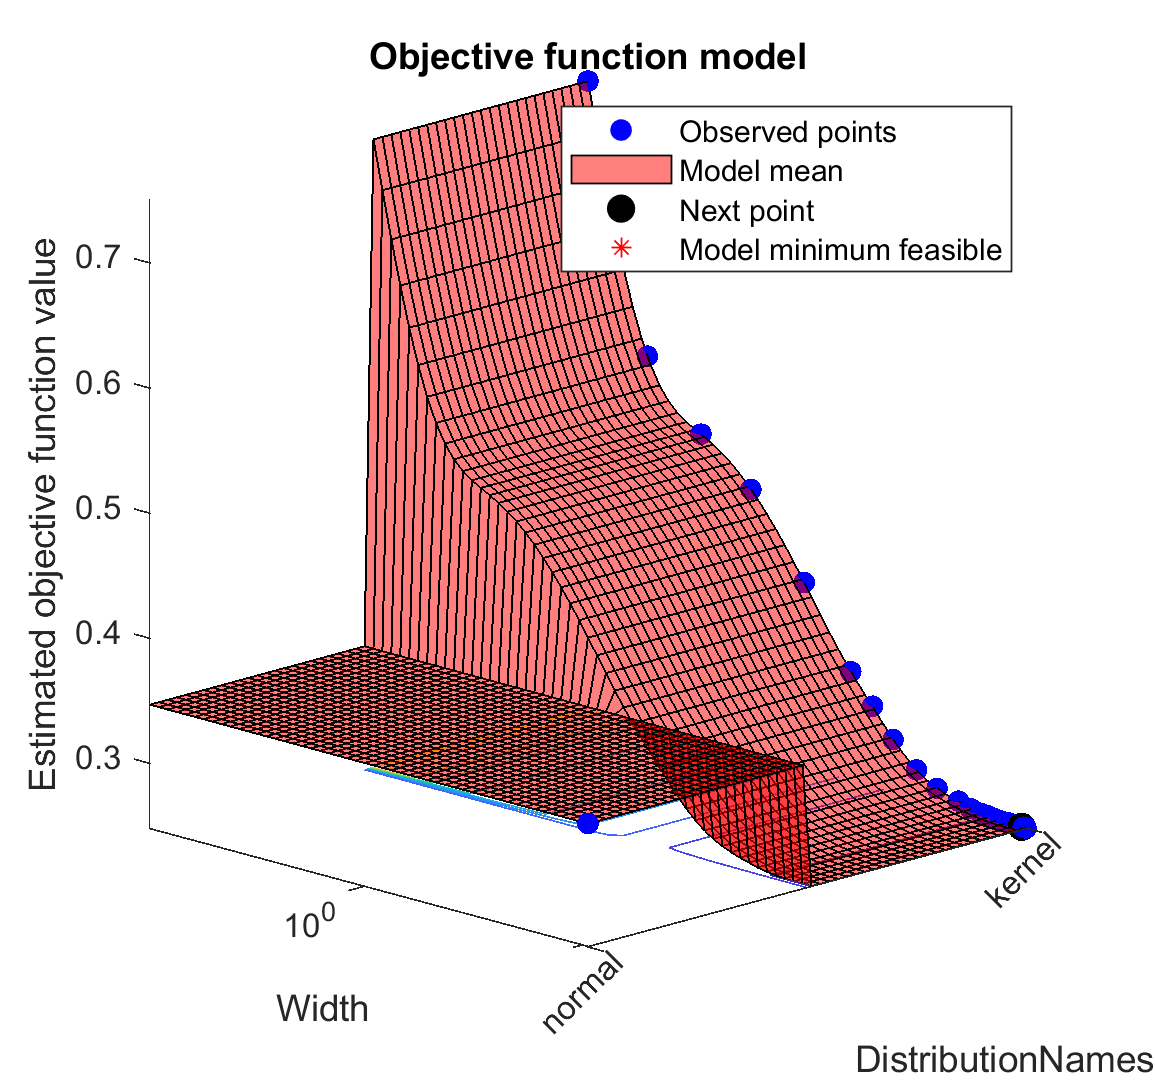


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 1011.5007 seconds
Total objective function evaluation time: 984.9032

Best observed feasible point:
    DistributionNames    Width 
    _________________    ______

         kernel          0.0932

Observed objective function value = 0.24844
Estimated objective function value = 0.24847
Function evaluation time = 20.506

Best estimated feasible point (according to models):
    DistributionNames     Width  
    _________________    ________

         kernel          0.098351

Estimated objective function value = 0.24843
Estimated function evaluation time = 22.4526



totalTime = endTime - startTime;
confusionMat = confusionchart(categorical(Y), predictions);
confusionMat = confusionchart(categorical(Y), predictions,'RowSummary','row-normalized','ColumnSummary','column-normalized');
fig_Position = fig.Position;
fig_Position(3) = fig_Position(3)*1.5;

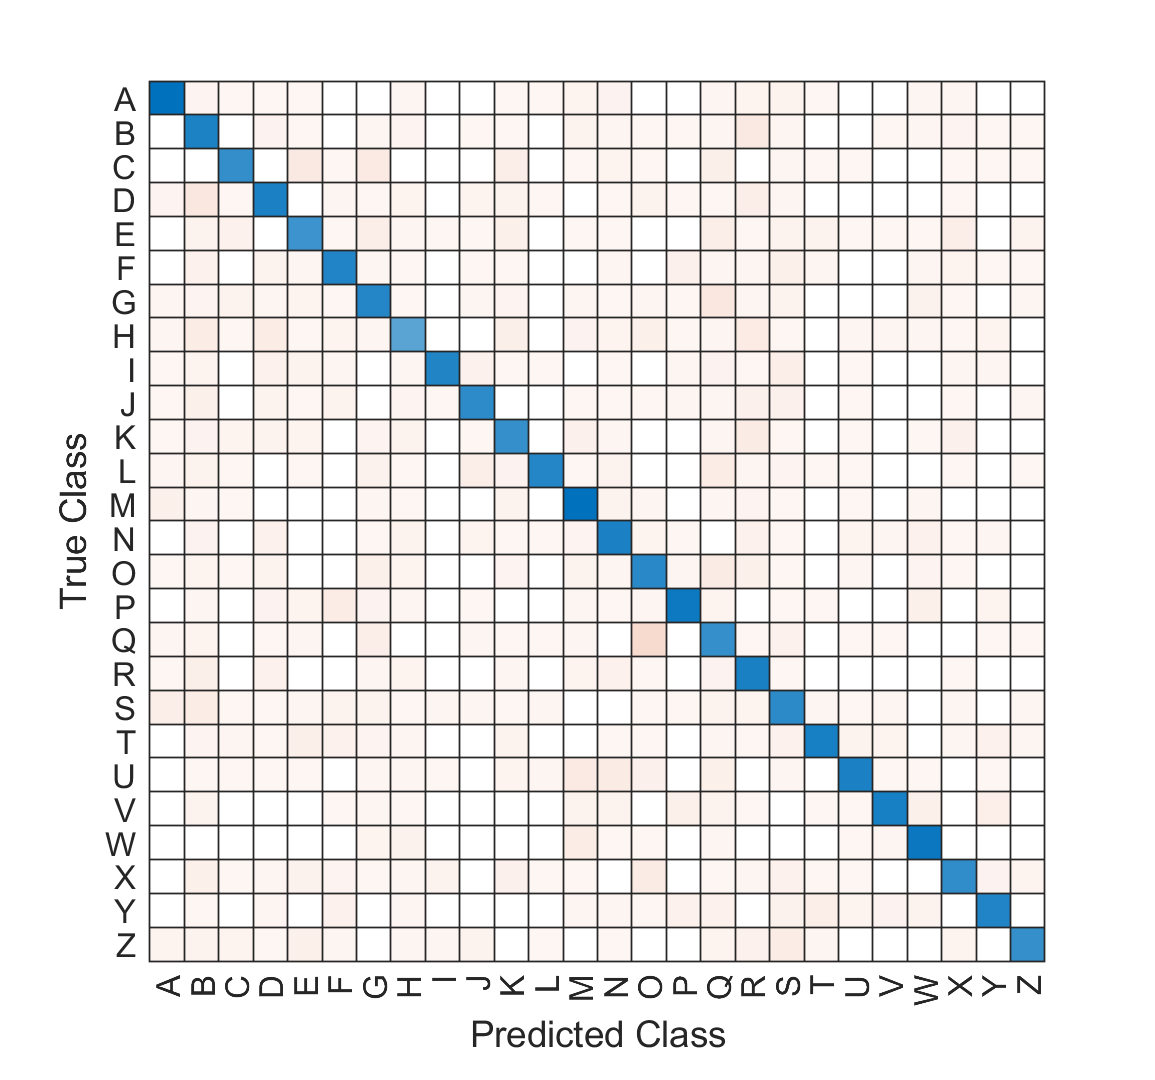

fig.Position = fig_Position;

fprintf("Training loss: %0.04f Test loss: %0.04f, standardised dataset: %d\n", ...
    trainingLoss, testLoss, nBayes.dataset.isStandardised);
fprintf("Total cpu time (seconds, includes optimization search): %02.04f", totalTime);

disp(nBayes);

Training loss: 0.2341 Test loss: 0.2518, standardised dataset: 1


Total cpu time (seconds): 4654.8750

  NBayesClass with properties:

            randomSeed: 300
                 debug: 0
               dataset: [1×1 LetterDatasetClass]
           nBayesModel: [1×1 ClassificationNaiveBayes]
                     x: [16000×12 table]
                     y: [16000×1 table]
                    xt: [4000×12 table]
                    yt: [4000×1 table]
      distNamesDefault: {1×12 cell}
       distNamesKernel: {1×12 cell}
             smoothBox: {'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'}
    smoothEpanechnikov: {1×12 cell}
           smootNormal: {1×12 cell}
        smoothTriangle: {1×12 cell}
         smoothUnsused: {1×16 cell}



### Results Conclusion

The results from all the tests are below:

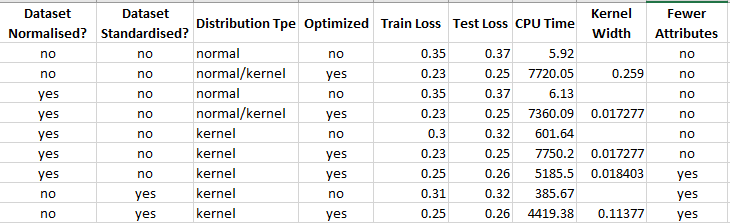

Conclusions drawn from the full dataset:

- Normalisation of the attributes has no effect.

- The kernal distribution is better than the normal distribution.

Conclusions drawn from using fewer features:

- Reducing the features has a very small effect on the training and test loss.

- Setting the prior distribution to the actual dataset distribution has little effect compared to the default. Setting it is prefereable: the values are calculated using the training dataset, and are known.

- The optimization task is quickest using fewer features, on a standardised dataset.

- The standardised dataset hyperparameter value for the optimized kernel width is reported as 0.11377

Further work on the dataset should use the standardised dataset with fewer features: the time reduction is great enough to justify the very small increase in loss of between 1% and 2%.

Matlab displays a warning advising the standardization of numeric predictors when optimizing using the width hyperparameter. Using the normalised dataset provides a noticeable reduction in the time taken to run the analysis tasks.